SPCOM - February  2024

## Input parameters

Create the structure that contains the environment constants.

Reinforcement Learning based Scheduler RLS

We adopt WiFi Parameters

Episodic procedure

clear
close all
Par.FileName='DQN_VecQ';
Par.Training=0; % 1 to train, 0 to present results
if Par.Training==1
    % rng("default")
    rng("shuffle")
    % Environment Parameters
    EnvCons.Frame=10^-2; % Frame duration in sec. 10 msec.
    EnvCons.NSlots=2500;    % Number Slots / Frame
    % EnvCons.Free=[250 2000]; % SF Patterm [# DL SYNC Slots, Free Slots;  (# UL SYNC Slots)]
    EnvCons.Free=[0 2500]; % SF Patterm [# DL SYNC Slots, Free Slots;  (# UL SYNC Slots)]
    EnvCons.Slot=EnvCons.Frame/EnvCons.NSlots;      % Slot duration in sec.
    EnvCons.Bits=90*8; % Packet size measured in bits: 8 bytes
    EnvCons.BSlot=[0 24 48 72 96 144 192 216];  % Number of served bits per Slot
    load 'probs_test3' % File contains BSlot probability for a channel model
    EnvCons.PrCumSum=cumsum(probs);
    clear probs
    % EnvCons.CohTime=3; % Coherence Time measured in frames; 1 by default
    EnvCons.BufferSize=100;   % Maximum number of packets in the queues
    EnvCons.MaxDelay=5*EnvCons.Frame; % Maximum Waiting time in sec.
    EnvCons.Factor=6;       % Factor to use more users where each user generates less traffic
    EnvCons.Lambda=0.005/EnvCons.Factor;  % Poisson mean time between arrival packets per flow.
    EnvCons.MaxFlows=150/EnvCons.Factor;  % Maximum number of flows per link


    % Next parameters are associated to the RL Agent instead of to the environment; Move to RLAgent???
    EnvCons.Ns=11; % Number of states (Ns)
    EnvCons.Na=11; % Number of actions
    EnvCons.Ac=1:EnvCons.Na;
    EnvCons.Delta=round(EnvCons.Free(2)/(EnvCons.Na-1));  % Min # os slots between two different actions
    EnvCons.NFrames=900;   % A Frame is a Step: Number of frames per episode
    EnvCons.NEpi=800;    % Number of Episodes

    %     [~,Opt_Ac]=max(RLAgent.Q');
    %     Id_Ac=[4 4 5 5 6 6 6 7 7 8 8];
    Par.FileName=strcat('Exploit',Par.FileName);

    % RL AGENT
    RLAgent.gamma=0.9; % 0.9 (Wenli)
    RLAgent.epsilon=1;
    RLAgent.epsDiscFactor=0.995;
    RLAgent.epsMIN=0.1;  % 0.1 (Wenli)
    RLAgent.Algorithm='DQN_s2';
    RLAgent.state_length=1;
    RLAgent.batch_size=32;
    RLAgent.state_size=2;
    RLAgent.layers=[RLAgent.state_size 64 32 EnvCons.Na];

    % DQN NETWORK
    RLAgent.arrayNet=makeNetwork(RLAgent);
    RLAgent.net=dlnetwork(RLAgent.arrayNet); % policy (critic) net
    RLAgent.target_net=RLAgent.net; % initializes both networks by sharing the same weights (target net)

    % EXPERIENCE REPLAY BUFFER
    RLAgent.buffer_size=10000;
    RLAgent.experienceBufferState=zeros(RLAgent.buffer_size,RLAgent.state_size);
    RLAgent.experienceBufferAction=zeros(RLAgent.buffer_size,1);
    RLAgent.experienceBufferReward=zeros(RLAgent.buffer_size,1);
    RLAgent.experienceBufferNextState=zeros(RLAgent.buffer_size,RLAgent.state_size);
    RLAgent.lastExperiencePointerNext=1; % points to the position of the last element + 1
    RLAgent.elementsInBuffer=0;

    % BEST NETWORK
    RLAgent.currentReward=0; % computes the current mean reward value
    RLAgent.maxMeanReward=-1000000;
    RLAgent.bestNet=RLAgent.net;
    RLAgent.numbSamplesMean=50; % number of samples to be averaged

    % OPTIMISER
    Optimiser.averageGrad = [];
    Optimiser.averageSqGrad = [];
    Optimiser.iteration = 0;
    Optimiser.learnRate = 0.001;% 0.0001;
    Optimiser.regularizationFactor = 0; % L2 regularisation factor; 0 if any regularisation is applied

    % WEIGTHS TRANSFER
    RLAgent.transfer_type='smoothing';
    RLAgent.transfer_it=0;
    RLAgent.update_step=1000; % periodical update
    RLAgent.tau=0.001;
else
    Par.FileName=strcat('Exploit',Par.FileName);
    load(Par.FileName)
    Par.Training=0;
end

## Training

if Par.Training==1
    % Variables to measure results
    Queue=zeros(EnvCons.NEpi,2);
    Pin=zeros(EnvCons.NEpi,2);
    Delay=zeros(EnvCons.NEpi,2); % Delay per Episode and Link
    Plost_Del=zeros(EnvCons.NEpi,2); % Counter Lost Packets/frame if waiting time is > Max Delay
    Plost_Buf=zeros(EnvCons.NEpi,2); % Counter Lost Packets/frame if packet arrives when buffer is full
    Pout=zeros(EnvCons.NEpi,2); % Counter Out Packets/frame
    Time_Reward=zeros(EnvCons.NEpi,1); % Average Reward per episode
    lossTrain=zeros(EnvCons.NEpi,1);  % LOSS


    for i_Epi=1:EnvCons.NEpi
        frame_loss=0;
        DelayQ=cell(1,2);

        % if mod(i_Epi, 100)==1
        %     display([Par.FileName,' it = ',num2str(i_Epi)])
        % end

        RLAgent.epsilon=max(RLAgent.epsMIN,RLAgent.epsilon*RLAgent.epsDiscFactor);

        % Reset the queues and generate randomly number of flows per queue
        EnvCons.NFlows=[randi(EnvCons.MaxFlows) randi(EnvCons.MaxFlows)];
        EnvCons.NQueues=sum(EnvCons.NFlows);

        % CHANNEL STATUS FOR EACH FRAME
        BSlot=rand(EnvCons.NFrames+1,EnvCons.NQueues);
        for i_Frame=1:EnvCons.NFrames
            for i_Flow=1:EnvCons.NQueues
                BSlot(i_Frame,i_Flow)=sum(EnvCons.PrCumSum<BSlot(i_Frame,i_Flow)); % GIVEN PROBABILITY
                BSlot(i_Frame,i_Flow)=EnvCons.BSlot(BSlot(i_Frame,i_Flow)+1); % Number of bits/slot
            end
        end
        EnvCons.Tb2=EnvCons.Slot./BSlot(1,:);
        [Obs,LogSig] = myResetFunEQ(EnvCons);

        for i_Frame=1:EnvCons.NFrames

            
            % UPDATE CHANNEL STATUS
            EnvCons.BSlotQ=BSlot(i_Frame,:); % Bits/Slot per queue
            EnvCons.Tb=EnvCons.Slot./EnvCons.BSlotQ; % Bit duration in sec. per queue
            EnvCons.Tb2=EnvCons.Slot./BSlot(i_Frame+1,:); % Bit duration in sec. per queue NEXT FRAME

            Action=GreedyActionSelection(RLAgent.net,[LogSig.muQ LogSig.muT],RLAgent.epsilon,EnvCons.Na); ...
                % selects the action using e-greedy NOTE THAT IN FACT STATES IS
            % A VECTOR
            Current_State=[LogSig.muQ LogSig.muT];
            [Obs,Reward,IsDone,LogSig]=myStepFunEQ(Action,LogSig,EnvCons); % takes action A and observes the enviroment

            % SAVE SARS TO EXPERIENCE BUFFER
            if RLAgent.lastExperiencePointerNext>RLAgent.buffer_size
                RLAgent.lastExperiencePointerNext=1; % circular buffer
            end
            RLAgent.experienceBufferState(RLAgent.lastExperiencePointerNext,:)=Current_State;
            RLAgent.experienceBufferAction(RLAgent.lastExperiencePointerNext,:)=Action;
            RLAgent.experienceBufferReward(RLAgent.lastExperiencePointerNext,:)=Reward;
            
            RLAgent.experienceBufferNextState(RLAgent.lastExperiencePointerNext,:)=[LogSig.muQ LogSig.muT]; % stores SARS' in the buffer
            RLAgent.elementsInBuffer=max(RLAgent.elementsInBuffer, RLAgent.lastExperiencePointerNext); % number of experiences in the buffer
            RLAgent.lastExperiencePointerNext=RLAgent.lastExperiencePointerNext+1;

            if RLAgent.elementsInBuffer>=RLAgent.batch_size

                % SELECT MINIBATCH
                selectedSamplesIndices=randperm(RLAgent.elementsInBuffer,RLAgent.batch_size); % selects randomly M samples
                StateBatch=RLAgent.experienceBufferState(selectedSamplesIndices,:);
                ActionBatch=RLAgent.experienceBufferAction(selectedSamplesIndices,:);
                RewardBatch=RLAgent.experienceBufferReward(selectedSamplesIndices,:);
                NextStateBatch=RLAgent.experienceBufferNextState(selectedSamplesIndices,:);
                estimation=RewardBatch+RLAgent.gamma*max(predict(RLAgent.target_net, NextStateBatch),[],2);
                % BACKPROPAGATION
                [loss,gradients,state] = dlfeval(@modelLoss,RLAgent.net,dlarray(double(StateBatch),'BC'),dlarray(double(estimation),'BC'),ActionBatch,Optimiser.regularizationFactor);
                RLAgent.net.State = state;
                % UPDATE
                Optimiser.iteration=Optimiser.iteration+1;
                [RLAgent.net,Optimiser.averageGrad,Optimiser.averageSqGrad] = adamupdate(RLAgent.net,gradients,Optimiser.averageGrad,Optimiser.averageSqGrad,Optimiser.iteration); %,Optimiser.learnRate);
                frame_loss=frame_loss+loss;
            end


            % WEIGHTS TRANSFER
            RLAgent.transfer_it=RLAgent.transfer_it+1;
            switch RLAgent.transfer_type
                case 'periodic'
                    if RLAgent.transfer_it==RLAgent.update_step
                        RLAgent.target_net.Learnables=RLAgent.net.Learnables;
                        RLAgent.transfer_it=0;
                    end
                case 'smoothing'
                    for n_layer = 1:numel(RLAgent.net.Learnables.Value)
                        RLAgent.target_net.Learnables.Value{n_layer}=RLAgent.tau*RLAgent.net.Learnables.Value{n_layer} + (1-RLAgent.tau)*RLAgent.target_net.Learnables.Value{n_layer};
                    end
            end


            % METRICS LOG
            % Average delay per frame and traffic
            for iq=1:EnvCons.NFlows(1)
                DelayQ{1}=[DelayQ{1} Obs.Delay{iq}]; % Observed Delays at UL
            end
            for iq=EnvCons.NFlows(1)+1:sum(EnvCons.NFlows)
                DelayQ{2}=[DelayQ{2} Obs.Delay{iq}]; % Observed Delays at DL
            end


            Plost_Del(i_Epi,1)=Plost_Del(i_Epi,1)+sum(Obs.Plost_Del(1:EnvCons.NFlows(1))); ...
                % Counter for the Lost Packets if waiting time>Max Delay in UL
            Plost_Del(i_Epi,2)=Plost_Del(i_Epi,2)+sum(Obs.Plost_Del(EnvCons.NFlows(1)+(1:EnvCons.NFlows(2)))); ...
                % Counter for the Lost Packets if waiting time>Max Delay in DL
            Plost_Buf(i_Epi,1)=Plost_Buf(i_Epi,1)+sum(Obs.Plost_Buf(1:EnvCons.NFlows(1))); ...
                % Counter for the Lost Packets if memory buffer is full in the UL
            Plost_Buf(i_Epi,2)=Plost_Buf(i_Epi,2)+sum(Obs.Plost_Buf(EnvCons.NFlows(1)+(1:EnvCons.NFlows(2)))); ...
                % Counter for the Lost Packets if memory buffer is full in the DL

            Pin(i_Epi,1)=Pin(i_Epi,1)+sum(Obs.Pin(1:EnvCons.NFlows(1))); ...
                % Counter for the IN Packets in the UL
            Pin(i_Epi,2)=Pin(i_Epi,2)+sum(Obs.Pin(EnvCons.NFlows(1)+(1:EnvCons.NFlows(2)))); ...
                % Counter for the IN Packets in the DL
            Pout(i_Epi,1)=Pout(i_Epi,1)+sum(Obs.Pout(1:EnvCons.NFlows(1))); ...
                % Counter for the OUT Packets in the UL
            Pout(i_Epi,2)=Pout(i_Epi,2)+sum(Obs.Pout(EnvCons.NFlows(1)+(1:EnvCons.NFlows(2)))); ...
                % Counter for the OUT Packets in the DL
            Queue(i_Epi,1)=Queue(i_Epi,1)+sum(LogSig.queueBits(1:EnvCons.NFlows(1))); ...
                % Counter for the bits in aggregated queue in the UL
            Queue(i_Epi,2)=Queue(i_Epi,2)+sum(LogSig.queueBits(EnvCons.NFlows(1)+(1:EnvCons.NFlows(2)))); ...
                % Counter for the bits in aggregated queue  in the DL

            Time_Reward(i_Epi)=Time_Reward(i_Epi)+Reward;

            lossTrain(i_Epi)=lossTrain(i_Epi)+frame_loss;

        end
        Delay(i_Epi,1)=mean(DelayQ{1});
        Delay(i_Epi,2)=mean(DelayQ{2});


        % SAVE THE BEST NETWORK
        iniIndex=max(1, i_Epi-RLAgent.numbSamplesMean+1); % when the number of available rewards is smaller than RLAgent.numbSamplesMean
        RLAgent.currentReward=mean(Time_Reward(iniIndex:i_Epi, 1));
        if RLAgent.currentReward>=RLAgent.maxMeanReward
            RLAgent.bestNet=RLAgent.net;
            RLAgent.maxMeanReward=RLAgent.currentReward;
            RLAgent.bestEpi=i_Epi;
        end

        i_Epi % EPISODE # i_Epi
    end

    Queue=Queue/EnvCons.NFrames;
    Pin=Pin/EnvCons.NFrames;
    Plost_Del=Plost_Del/EnvCons.NFrames;
    Plost_Buf=Plost_Buf/EnvCons.NFrames;
    Pout=Pout/EnvCons.NFrames;
    Time_Reward=Time_Reward/EnvCons.NFrames;

    lossTrain=lossTrain/EnvCons.NFrames;

    clear i_Epi Current_state i_Frame Empty_Frames
    clear S isDone frame_loss

    DQN_net=RLAgent.net;
    save(Par.FileName)
end

## Graphic Results

### Queues, Pin, Pout

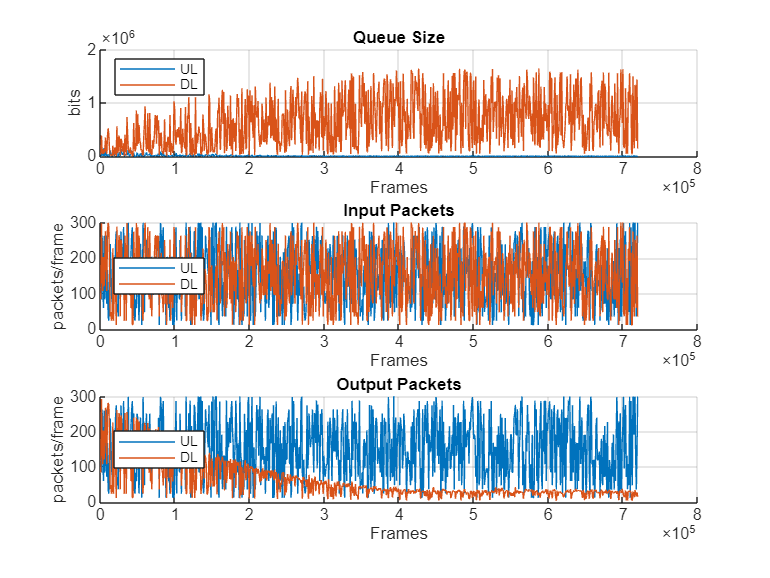

if Par.Training==0
    figure
    t_axe=(1:EnvCons.NEpi)*EnvCons.NFrames;
    subplot(3,1,1) % Queue Size Evolution
    hold on
    for iLink=1:2
        plot(t_axe,Queue(:,iLink))
    end
    hold off
    grid
    title('Queue Size')
    ylabel('bits')
    xlabel('Frames')
    legend('UL','DL','Location','best')

    subplot(3,1,2) % Input Packets
    hold on
    for iLink=1:2   % EnvCons.NQueues
        plot(t_axe,Pin(:,iLink))
    end
    hold off
    grid
    title('Input Packets')
    ylabel('packets/frame')
    xlabel('Frames')
    legend('UL','DL','Location','west')

    subplot(3,1,3) % Output Packets
    hold on
    for iLink=1:2  %EnvCons.NQueues
        plot(t_axe,Pout(:,iLink))
    end
    hold off
    grid
    title('Output Packets')
    ylabel('packets/frame')
    xlabel('Frames')
    legend('UL','DL','Location','west')
end

### Lost Packets per frame and Average Delay

L1 =     0.0001    0.3709


L2 =     0.0000    0.4883


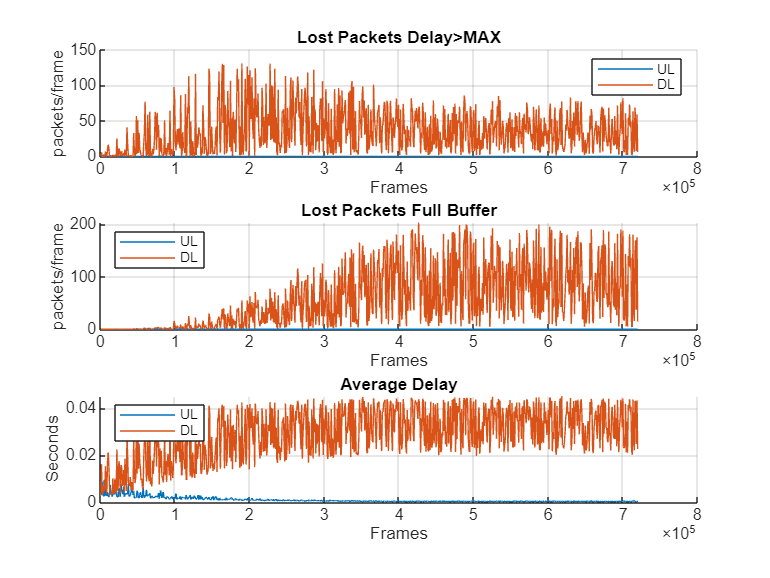

Av_Delay =     0.0009    0.0290


if Par.Training==0
    figure
    subplot(3,1,1) % Lost Packets
    hold on
    for iLink=1:2
        plot(t_axe,Plost_Del(:,iLink))
    end
    hold off
    grid
    title('Lost Packets Delay>MAX')
    ylabel('packets/frame')
    xlabel('Frames')
    legend('UL','DL','Location','best')
    L1=sum(Plost_Del)./(sum(Pout)+sum(Plost_Del))

    subplot(3,1,2) % Lost Packets
    hold on
    for iLink=1:2
        plot(t_axe,Plost_Buf(:,iLink))
    end
    hold off
    grid
    title('Lost Packets Full Buffer')
    ylabel('packets/frame')
    xlabel('Frames')
    legend('UL','DL','Location','best')
    L2=sum(Plost_Buf)./(sum(Pout)+sum(Plost_Buf))

    subplot(3,1,3) % Average Delay
    hold on
    for iLink=1:2
        plot(t_axe,Delay(:,iLink))
    end
    hold off
    grid
    title('Average Delay')
    ylabel('Seconds')
    xlabel('Frames')
    legend('UL','DL','Location','best')
    Av_Delay=mean(Delay)
end

### Reward and Loss

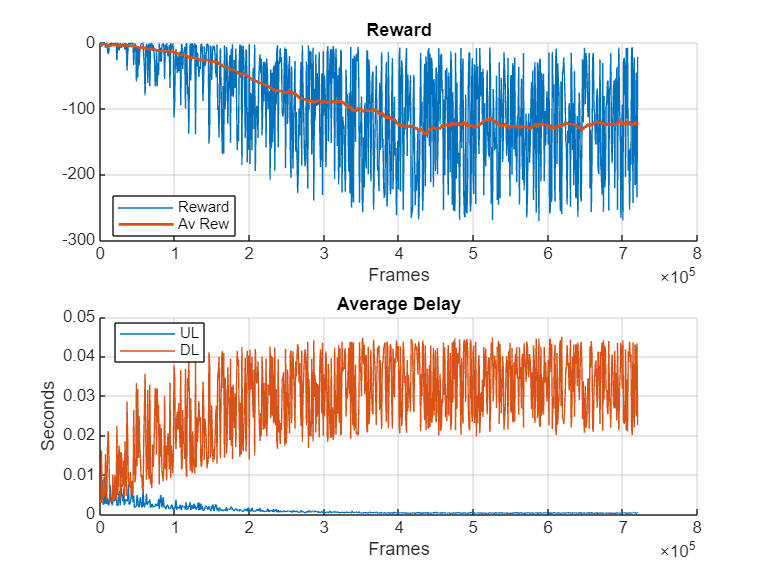

Av_Delay =     0.0009    0.0290


if Par.Training==0
    figure
    subplot(2,1,1) % Reward
    hold on
    plot(t_axe,Time_Reward)
    Av_Reward=zeros(size(Time_Reward));
    for i_epi=1:EnvCons.NEpi
        Av_Reward(i_epi)=sum(Time_Reward(max(1,i_epi-99):i_epi))/length(max(1,i_epi-99):i_epi);
    end
    plot(t_axe,Av_Reward,'LineWidth',1.5)
    grid
    title('Reward')
    xlabel('Frames')
    legend('Reward','Av Rew','Location','best')

    subplot(2,1,2) % Loss Function
    hold on
    % plot(t_axe,lossTrain)
    % Av_Loss=ones(size(lossTrain))*mean(lossTrain);
    % plot(t_axe,Av_Loss,'LineWidth',1.5)
    % grid
    % title('Av Loss Function')
    % xlabel('Frames')
    % legend('Loss','Av Loss','Location','best')

    % Average Delay for PAPER
    for iLink=1:2
        plot(t_axe,Delay(:,iLink))
    end
    hold off
    grid
    title('Average Delay')
    ylabel('Seconds')
    xlabel('Frames')
    legend('UL','DL','Location','best')
    Av_Delay=mean(Delay)

    clear t_axe iq
end

## Auxiliary functions

function network = makeNetwork(RLAgent)
    network = [featureInputLayer(RLAgent.layers(1), 'Name', ['input_features_' num2str(1)])]; % Input features
    first = 0;
    for i = 2:numel(RLAgent.layers)
        switch first
            case 0
                first = 1;
            case 1
                network = [network reluLayer('Name', ['relu_layer_' num2str(i-1)])]; % ReLU
        end
        network = [network fullyConnectedLayer(RLAgent.layers(i), 'WeightsInitializer', 'Glorot', 'Name', ['fc_layer_' num2str(i)])]; % FC
    end
end

function A = GreedyActionSelection(net, state, epsilon, Na)
    a=rand(); % https://es.mathworks.com/help/matlab/ref/rand.html random number from [0,1]
    if a<epsilon  
        A=randi([1,Na]); % https://es.mathworks.com/help/matlab/ref/randi.html RANDOM ACTION
    else  
        actionValue=predict(net,state); % Obtain the 4 outputs
        [~,A]=max(actionValue);
    end   
end

function [loss,gradients,state] = modelLoss(net,X,new_Q_values,actions,reg_factor)
    [Y,state] = forward(net,X); % Forward data through network
    old_Q_values = Y(sub2ind(size(Y), actions', 1:size(Y,2)));
    loss = mse(dlarray(double(old_Q_values),'CB'),new_Q_values); % Calculate cross-entropy loss
    gradients = dlgradient(loss,net.Learnables); % Calculate gradients of loss with respect to learnable parameters
    gradients = dlupdate(@(g,p) g + reg_factor*p,gradients,net.Learnables);
end